## investigate expanded input model function

In this script I try to reproduce what happens with the model when expanding it to a multi population model. 

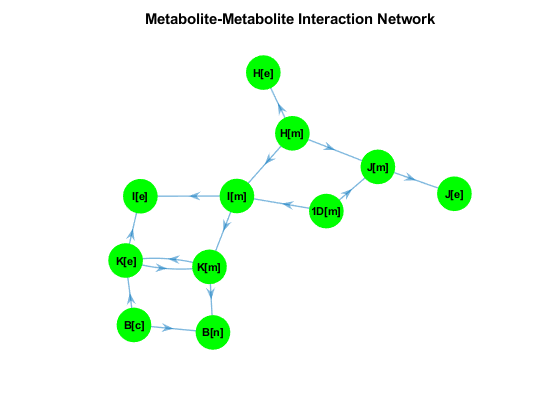

addpath(genpath('\\atlas.uni.lux\FSTC_SYSBIO\0- UserFolders\Leonie.THOMAS\projects\20241230_toy_model_multi_model_construction'))
load_toy_model


% 3 external reactions and one sink reaction
ReactionFormulas = {' <=> A[e]','A[e] -> A[c]','A -> C','A -> D', 'C[c] <=> C[e]', 'D[c] <=> D[e]' ,'A -> ', 'D[e] -> ', 'C[e] -> '};
ReactionNames = {'EX_v1','v2','v3', 'v4', 'EX_v5', 'EX_v6', 'SK_v7', 'EX_v8', 'EX_v9'};
GeneNames={'Gene1','Gene2','Gene3', 'Gene4', 'Gene5', 'Gene6', 'Gene7', 'Gene8', 'Gene9'}; % ? 

fig1_model = createModel(ReactionNames, ReactionNames, ReactionFormulas,'grRuleList',GeneNames);

Adding the following Metabolites to the model:
A[c]
A[e]
C[c]
C[e]
D[c]
D[e]
addMultipleReactions: Adding the following reactions to the model:
EX_v1		<=>	A[e] 
v2	A[e] 	->	A[c] 
v3	A[c] 	->	C[c] 
v4	A[c] 	->	D[c] 
EX_v5	C[c] 	<=>	C[e] 
EX_v6	D[c] 	<=>	D[e] 
SK_v7	A[c] 	->	
EX_v8	D[e] 	->	
EX_v9	C[e] 	->	


 
clearvars -except solverOK, clc, close all

%% INPUTS: A table contained the genes names and the bulk RNAa-seq values
% A consistent model
% A dictionary between the data IDs and the model IDs
% The single-cell data should be stored in a Folder called Dataset

%run optimization
run_optimization=0;
printLevel=1;

%Path
% % % changeCobraSolver('ibm_cplex')
% % % user_path='C:\Users\maria.pacheco\OneDrive - University of Luxembourg\Documents\GitHub\scFASTCORMICS_o';
user_path='C:\Users\leonie.thomas\scFASTCORMICS';
addpath(genpath(user_path));

% Data_1
% % % biodbnet = readtable([user_path,'\dico_biodbnet.txt']); % The dictionary should map the model genes id to the data ids
biodbnet = readtable(['dico_biodbnet.txt']); % The dictionary should map the model genes id to the data ids
load('simpleRev_recon3.mat','model');
model.lb(find(ismember(model.rxns,'EX_h2o2[e]')))=0;
model.lb(find(ismember(model.rxns,'EX_o2s[e]')))=0;
model.lb(find(ismember(model.rxns,'EX_oh1[e]')))=0;
model.ub(find(ismember(model.rxns,'EX_oh1[e]')))=0;
model.lb(find(ismember(model.rxns,'EX_ppi[e]')))=0;
model.lb(find(ismember(model.rxns,'sink_fe3[c]')))=0;
model.lb(find(ismember(model.rxns,'sink_band[c]')))=0;
model.ub(find(ismember(model.rxns,'sink_band[c]')))=0;

% biomass_reaction / biomass_maintenance / biomass_maintenance_noTrTr
biomass_reaction='biomass_reaction'; %Recon3D biomass
[NUM,TXT,RAW]=xlsread('medium_withconc.xlsx');
medium=[RAW(:,2); 'hdl_hs[e]'; 'nh4[e]'; 'so3[e]'; 'tsul[e]'; 'tag_hs(e)'];
T=table(RAW(:,1),RAW(:,2),NUM,'VariableNames',{'medium_rxns_keep','medium_composition','met_Conc_mM'});
not_medium='NONE'; % 'NONE'
unpenalizedSystems = {'Transport, endoplasmic reticular';
    'Transport, extracellular';
    'Transport, golgi apparatus';
    'Transport, mitochondrial';
    'Transport, peroxisomal';
    'Transport, lysosomal';
    'Transport, nuclear'};

% uncomment if you get an error concerning eval
feature astheightlimit 2000;
function_keep=struct();
function_keep.biomass=biomass_reaction;
function_keep.medium=medium; %'' %medium
function_keep.obj=biomass_reaction;
function_keep.obj=[function_keep.obj; cellfun(@(c)['EX_' c],medium,'uni',false)]; %keep all medium
function_keep.not_medium=not_medium;
unpenalized = model.rxns(ismember(vertcat(model.subSystems{:}),unpenalizedSystems));
% optional_settings.unpenalized = unpenalized; %don't put transporters to core
function_keep.unpenalized = unpenalized; %don't put transporters to core

mm = constrain_model_rFASTCORMICS(model, function_keep.medium, function_keep.not_medium, function_keep.biomass, function_keep.obj);

Warning metaboltes with X in their Formulas these inputs are closed
Warning metaboltes with Y in their Formulas these inputs are closed


fields_to_keep={'S','rxns', 'mets', 'metFormulas','genes', 'rules', 'grRules', 'b', 'rxnGeneMat','c', 'lb', 'ub', 'rev', 'subSystems','metFormulas'};
addpath(genpath("C:\Users\leonie.thomas\scFASTCORMICS"))
number_of_cluster = 2;
run_toy_model = 1;
number_of_cluster = 2;
result_model = build_expanded_input_model(mm, number_of_cluster,run_toy_model, fields_to_keep)

result_model = struct with fields:
             S: [38×40 double]
             b: [38×1 double]
             c: [40×1 double]
         genes: {40×1 cell}
       grRules: {40×1 cell}
            lb: [40×1 double]
          mets: {38×1 cell}
           rev: [40×1 double]
         rules: {40×1 cell}
    rxnGeneMat: [40×40 double]
          rxns: {40×1 cell}
            ub: [40×1 double]


ans =    (2,1)       -2
   (3,1)       -2
   (4,1)       -2
   (5,1)        2
   (9,1)       -2
  (12,1)       -1
  (14,1)       -2
  (15,1)       -2
  (16,1)       -2
  (17,1)        2
  (21,1)       -2
  (24,1)       -1
  (25,1)        1
  (26,1)        1
  (27,1)        1
  (28,1)        1
  (29,1)        1
  (30,1)        1
  (31,1)       -1
  (32,1)        2
  (34,1)        2
  (35,1)        2
  (36,1)        2
  (37,1)        2
  (38,1)        2


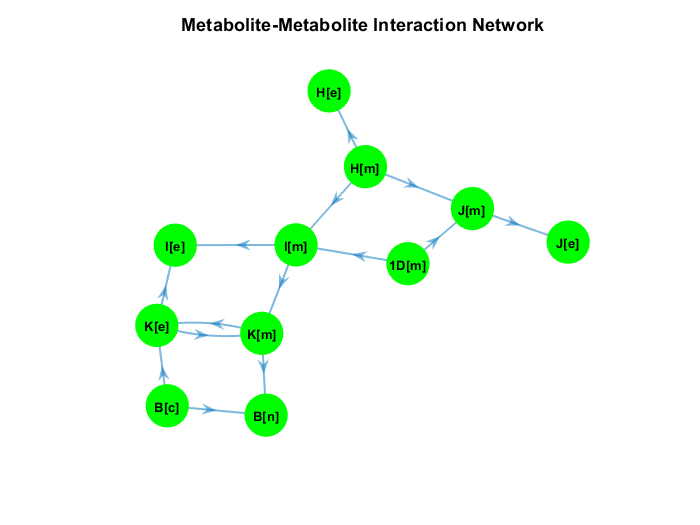

graphObj=createMetIntrcNetwork(toy_model,toy_model.mets);
set(gcf,'Visible','on'); % produce figure as pop up since live editor does

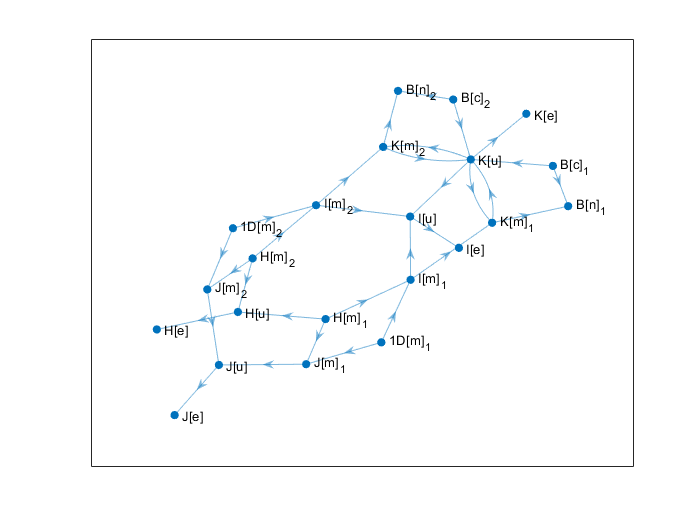

plot(graphObj)

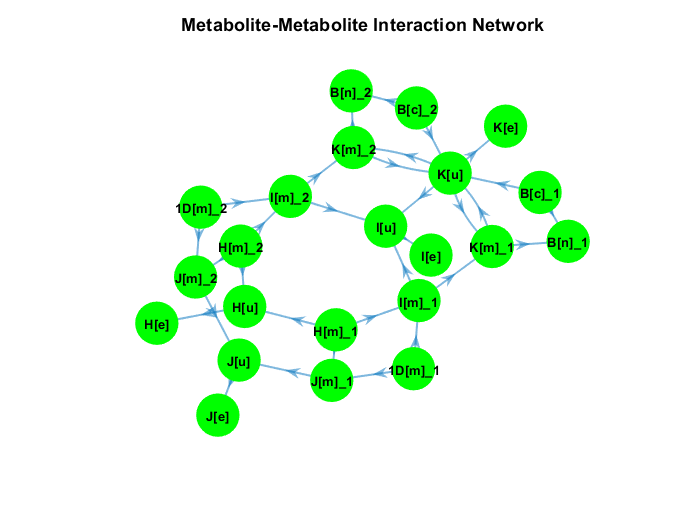

run_toy_model = 0; 
result_toy_model = build_expanded_input_model(toy_model, number_of_cluster,run_toy_model, fields_to_keep);
graphObj=createMetIntrcNetwork(result_toy_model,result_toy_model.mets);
set(gcf,'Visible','on'); % produce figure as pop up since live editor does

reference_model=createModel;
%reference_model=addReaction(reference_model,'R1', '-> A[e]');
%reference_model=addReaction(reference_model,'R2', 'A[c] + B[c] -> C[c] + 1D[m]');
%reference_model=addReaction(reference_model,'R3', ' C[g] + 1E[g] ->  G[g]');
reference_model=addReaction(reference_model,'R4', ' 1D[m] + H[m]  -> I[m] + J[m] ');
%reference_model=addReaction(reference_model,'R5', ' <=> 1E[e] ');
reference_model=addReaction(reference_model,'R6', '<=> H[e] ');
%reference_model=addReaction(reference_model,'R7', '<=> G[e] ');
reference_model=addReaction(reference_model,'R8', '<=> J[e]');
reference_model=addReaction(reference_model,'R9', '-> B[n] ');
reference_model=addReaction(reference_model,'R10', '<=> I[e]');
reference_model=addReaction(reference_model,'R11', 'I[m] + K[e] <=> I[e] + K[m]');
reference_model=addReaction(reference_model,'R12', 'B[c] + K[m] <=> B[n] + K[e] ');
reference_model=addReaction(reference_model,'R13', 'J[m] <=> J[e]');
%reference_model=addReaction(reference_model,'R14', 'G[g] <=> G[e] ');
reference_model=addReaction(reference_model,'R15', 'H[m] <=> H[e]');
reference_model=addReaction(reference_model,'R16', 'K[m] <=> ');
%reference_model=addReaction(reference_model,'R17', '1E[g] <=> 1E[e] ');
%reference_model=addReaction(reference_model,'R18', 'A[c] <=> A[e] ');
%reference_model=addReaction(reference_model,'R19', 'C[c] <=> C[g] ');
reference_model=addReaction(reference_model,'R20', 'K[e] <=> ');
    
reference_model.rev=zeros(numel(reference_model.rxns),1);
reference_model.rev(reference_model.lb<0)=1;
reference_model.rules={'x(1)';'x(2)';'x(3)';'x(4)';'x(5)';'x(6)';'x(7)';'x(8)';'x(9)';'x(10)';'x(11)'};%;'x(12)';'x(13)';'x(14)';'x(15)'};% ;'x(16)';'x(17)';'x(18)'; 'x(19)';'x(20)'};
reference_model.genes={'GA';'GB';'GC';'GD';'GE';'GF';'GG';'GH';'GI';'GJ';'GK'};%;'GL';'GM';'GN';'GO'};%;'GP';'GQ';'GR';'GS'; 'GT'};
reference_model = buildRxnGeneMat(reference_model);
toy_model=reference_model;

toy_model.S

Unable to resolve the name toy_model.S.



generic_input_reconstruction=mm;
generic_input_reconstruction=simplifyDuplicatedGenesFastbox(generic_input_reconstruction,1);
best=[];
plot_formula = 1;
run_toy_model=0;
number_of_cluster = 3;
fields_to_keep={'S','rxns', 'mets', 'metFormulas','genes', 'rules', 'grRules', 'b', 'rxnGeneMat','c', 'lb', 'ub', 'rev', 'subSystems','metFormulas'};


generic_input_reconstruction.rxns = strrep(generic_input_reconstruction.rxns,'_','');



model = toy_model;